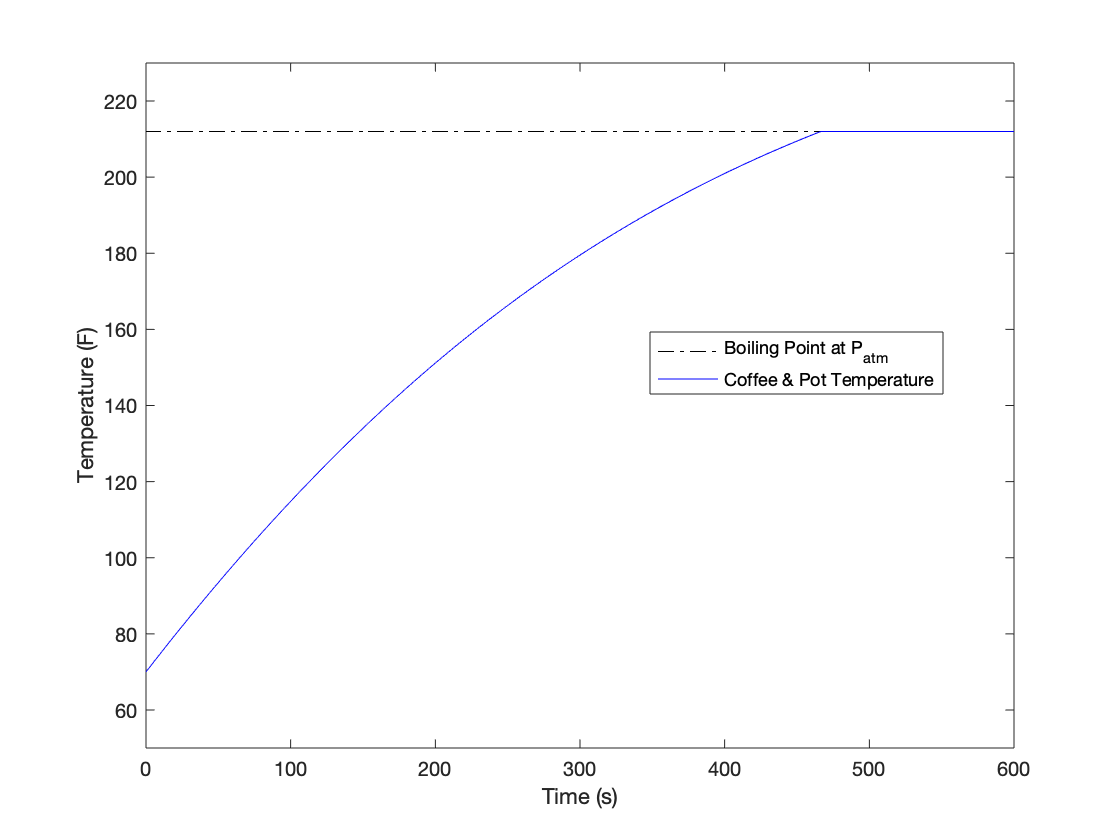

% Create variables
c_al = 0.12; % btu/lbm/F (Aluminum), specific heat
c_w = 1; % btu/lbm/F (water), specific heat
time = 0:0.5:600; % seconds
t_room = 70;
hA = 0.5; % btu/(hr x F)
k = 5 * 10^(-9); % btu/(hr x R^4)
m_pot = .288; %lbm
m_w = .5318; %lbm of water
Q_loss = 0;
y = []; % temp vector
y(1) = 70;
Q_in = 1000/3600; % (btu per hour)*(hr/3600s)
for i = 1: length(time)-1
    Q_net = Q_in - Q_loss;
    y(i+1) = (Q_net / (m_pot * c_al + m_w * c_w)) * .5 + y(i);
    Q_loss = (hA * (y(i+1) - t_room) + k * ((y(i+1) + 460).^4 - (t_room + 460).^4))/3600;
    if y(i+1) > 212
        y(i+1) = 212;
    end
end
boiling_temp = ones(1,length(time)) .* 212;
plot(time, boiling_temp,'k-.')
hold on
plot(time(1:end), y, 'b-')
legend('Boiling Point at P_a_t_m', 'Coffee & Pot Temperature', 'Location',"best")
xlabel('Time (s)')
ylabel('Temperature (F)')
axis([0 600 50 230])